# 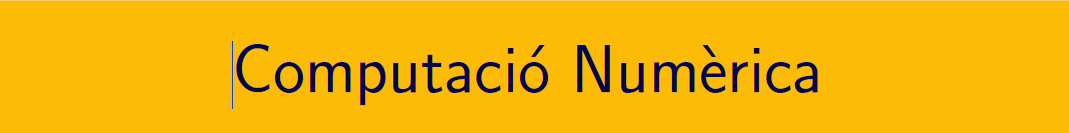

================================================================================

# Pràctica 12. Equacions diferencials ordinàries (I).

`Document preparat per M. Àngela Grau Gotés - 19 de maig de 2022`

## APRENEM... 

## **PVI  **$y^{\prime}(t)=y(t)+t^2\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

### MATLAB® - Solució analítica 

Consulteu l'ajuda de la comanda [DSOLVE](https://es.mathworks.com/help/symbolic/dsolve.html)

syms y(t)
eqn = diff(y,t) == t^2+y;
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = 3\,{\mathrm{e}}^{t}-2\,t-t^{2}-2$$

La solució es pot respresentar a l'interval [0,1]

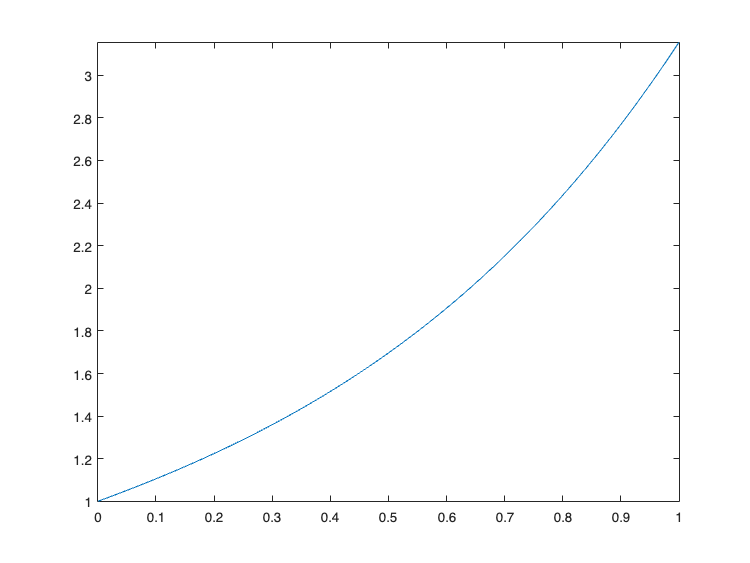

fplot(ySol,[0,1])

**Isoclines del camp de direccions y'=f(t,y)**

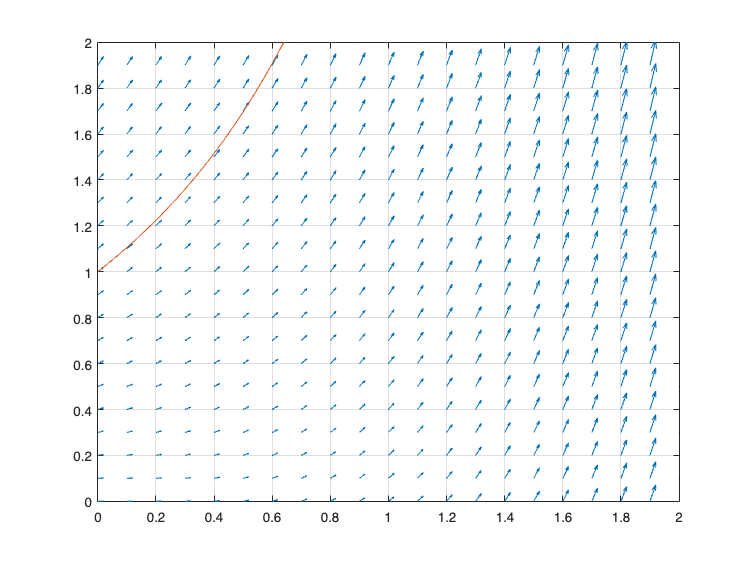

t=0:0.1:2; 
y=0:0.1:2;
[TT,YY] = meshgrid(t,y);
DT = ones(size(TT));
f = @(t,y)(t.^2+y);
DY = f(TT,YY);
% Gràfic
figure(1)
quiver(TT,YY,DT,DY);grid,axis([0,2,0,2])
hold on
fplot(ySol,[0,1]), hold off

### Solucions aproximades numèricament

#### `Mètode d'Euler per h = 0.2, h = 0.1 ....`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(t^2+y);
h = 0.2;
x = a:h:b; 
[ Y1 ] = Euler( f,a,b,h,alpha );
errorlocal = abs(Y1-double(ySol(x)))

errorlocal =             0     0.024208     0.067474      0.13676       0.2411      0.39222


errorGlobal = abs(Y1(end)-double(ySol(b)))

errorGlobal =       0.39222

table(x',Y1',errorlocal','Variablenames',{'t','Euler','error_local'})

ans = 6×3 table
     t     Euler     error_local
    ___    ______    ___________
      0         1            0  
    0.2       1.2     0.024208  
    0.4     1.448     0.067474  
    0.6    1.7696      0.13676  
    0.8    2.1955       0.2411  
      1    2.7626      0.39222  

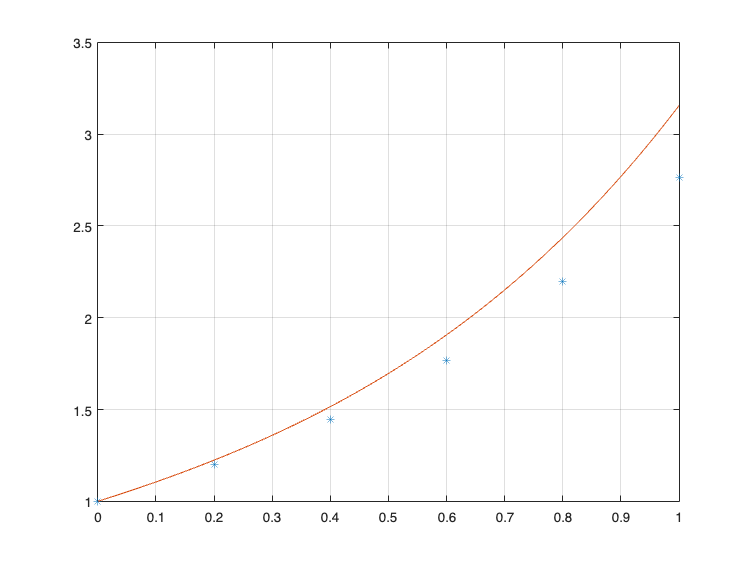

t=linspace(a,b);
plot(x,Y1,'*',t,ySol(t)),grid

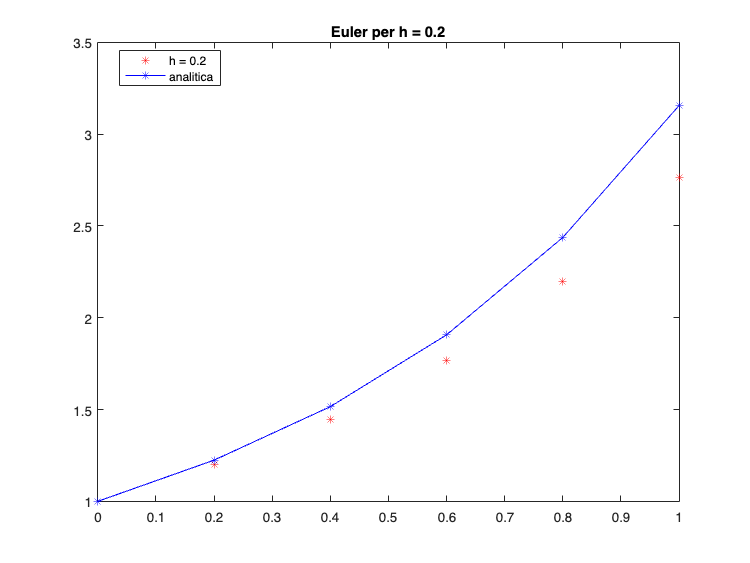

plot(x,Y1,'*r',x,ySol(x),'b-*'), title(['Euler per h = ', num2str(h)]), legend('h = 0.2','analitica','Location','best')

#### `Mètode d'Euler modificat`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(t^2+y);
h = 0.2;
x = a:h:b;

[ YM1 ] = EulerMod( f,a,b,h,alpha );
errorlocal = abs(YM1-double(ySol(x)));
errorGlobal = abs(YM1(end)-double(ySol(b)))

errorGlobal =      0.031242

table(x',YM1',errorlocal','Variablenames',{'t','EulerMod','error_local'})

ans = 6×3 table
     t     EulerMod    error_local
    ___    ________    ___________
      0          1              0 
    0.2      1.222      0.0022083 
    0.4     1.5096      0.0058341 
    0.6      1.895       0.011396 
    0.8     2.4171       0.019571 
      1     3.1236       0.031242 

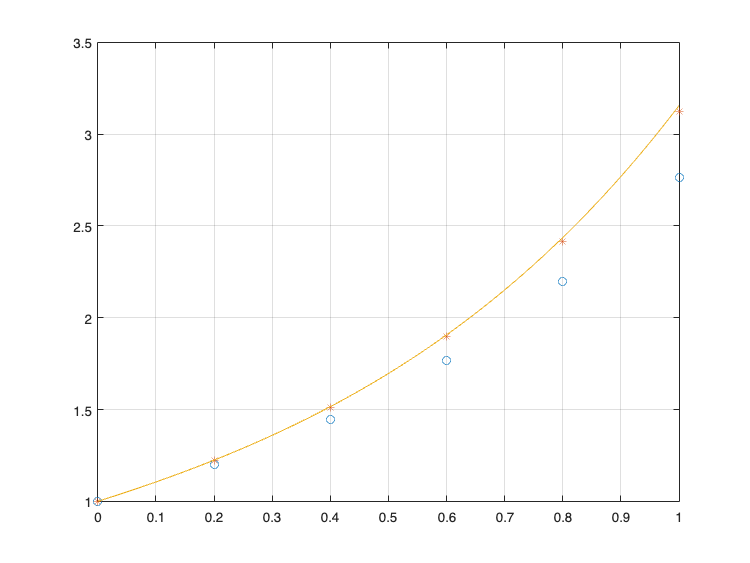

t=linspace(a,b);
plot(x, Y1,'o', x,YM1,'*',t,ySol(t)),grid

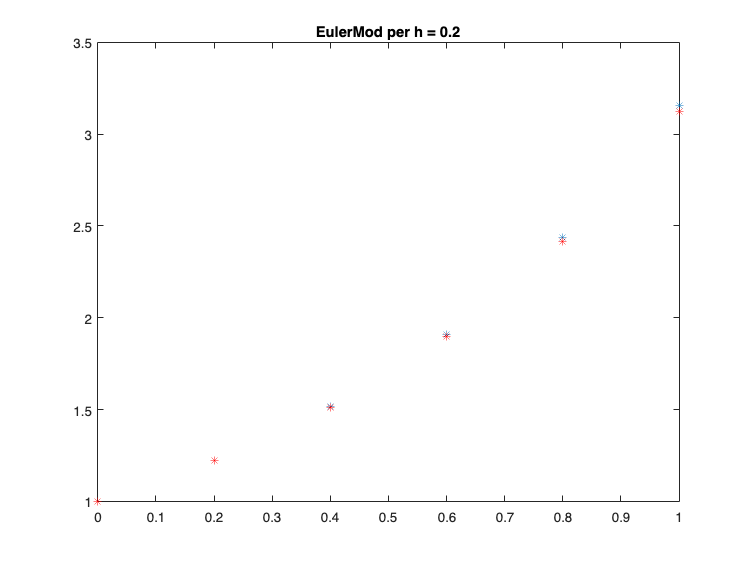

plot(x,ySol(x),'*',x,YM1,'*r'), title(['EulerMod per h = ', num2str(h)])

#### `Mètode de Heun`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(t^2+y);
h = 0.2;
x = a:h:b;

[ YH1 ] = EulerMill( f,a,b,h,alpha );
errorlocal = abs(YH1-double(ySol(x)));
errorGlobal = abs(YH1(end)-double(ySol(b)))

errorGlobal =      0.015763

table(x',YH1',errorlocal','Variablenames',{'t','EulerMill','error_local'})

ans = 6×3 table
     t     EulerMill    error_local
    ___    _________    ___________
      0          1               0 
    0.2      1.224      0.00020827 
    0.4     1.5141       0.0013941 
    0.6     1.9024       0.0039788 
    0.8     2.4281       0.0085221 
      1     3.1391        0.015763 

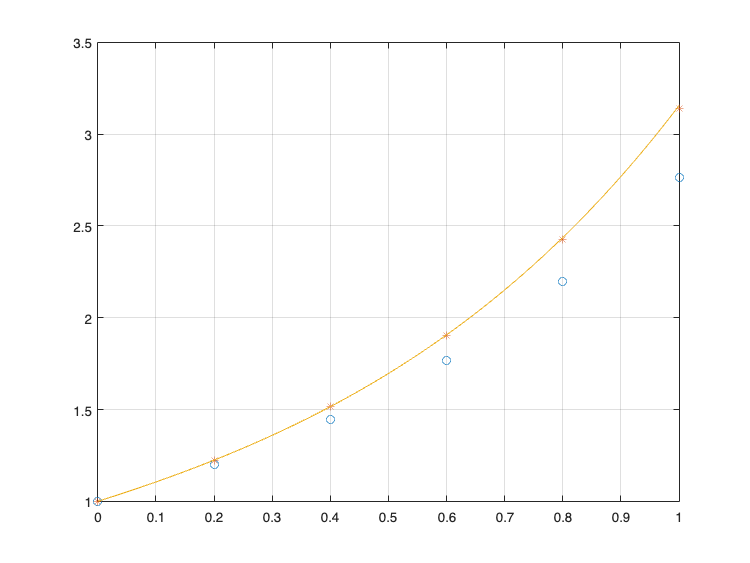

t=linspace(a,b);
plot(x, Y1,'o', x,YH1,'*',t,ySol(t)),grid

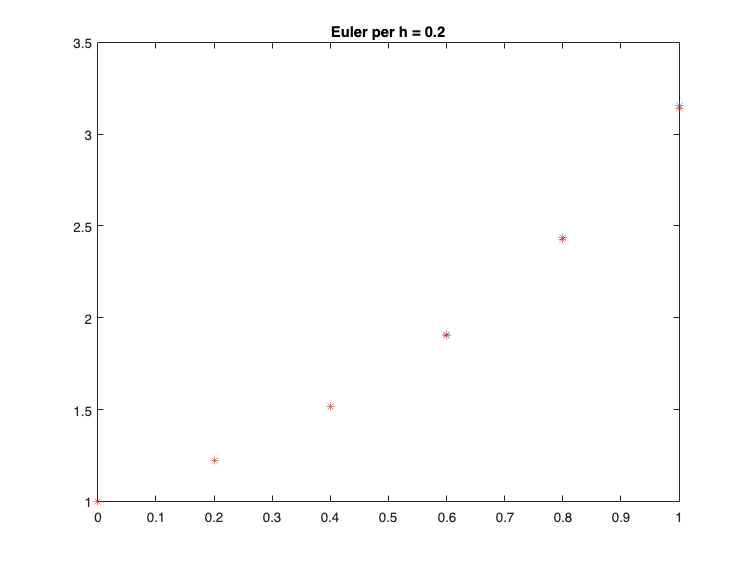

plot(x,ySol(x),'*',x,YH1,'*r'), title(['Euler per h = ', num2str(h)])

#### `Mètode RK4`

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(t^2+y);
h = 0.2;
x = a:h:b;

[ YK1 ] = RK4( f,a,b,h,alpha );
errorlocal = abs(YK1-double(ySol(x)));
errorGlobal = abs(YK1(end)-double(ySol(b)))

errorGlobal =    4.0337e-05

table(x',YK1',errorlocal','Variablenames',{'t','EulerMill','error_local'})

ans = 6×3 table
     t     EulerMill    error_local
    ___    _________    ___________
      0          1               0 
    0.2     1.2242      1.6078e-06 
    0.4     1.5155      5.4036e-06 
    0.6     1.9063      1.2277e-05 
    0.8     2.4366      2.3406e-05 
      1     3.1548      4.0337e-05 

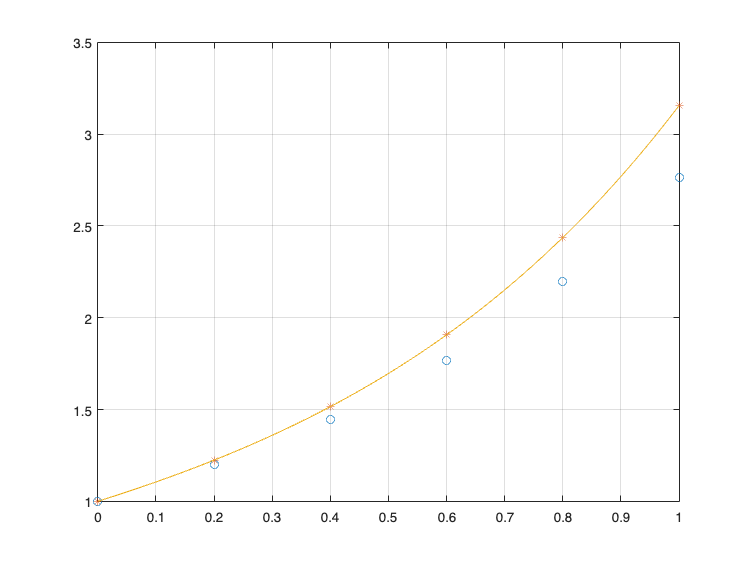

t=linspace(a,b);
plot(x, Y1,'o', x,YK1,'*',t,ySol(t)),grid

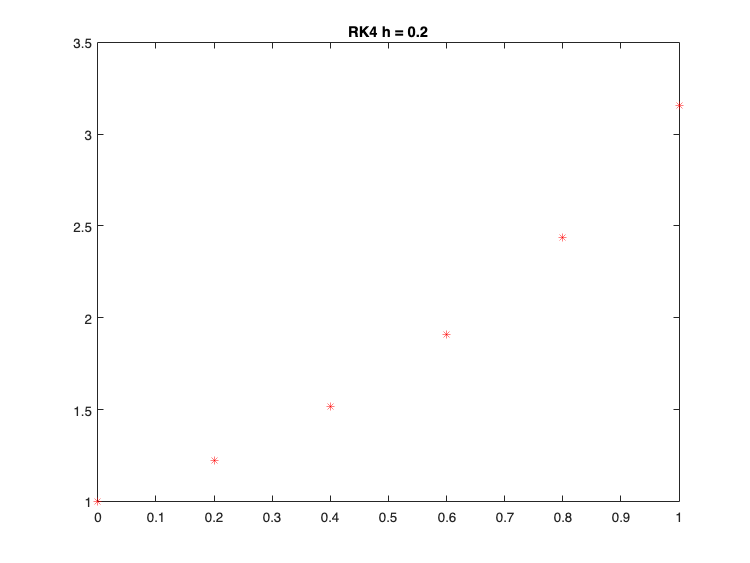

plot(x,ySol(x),'*',x,YK1,'*r'), title(['RK4 h = ', num2str(h)])

#### `Solvers de MATLAB®: ode23, ode45`

tspan = [0 1];
y0 = 1;        
ode = @(t,y)(t^2+y);
[t1,y1] = ode23(ode, tspan, y0);
disp([t1,y1])

            0            1
         0.08       1.0835
         0.18       1.1992
         0.28        1.331
         0.38       1.4824
         0.48       1.6578
         0.58       1.8617
         0.68       2.0992
         0.78       2.3759
         0.88       2.6982
         0.98       3.0728
            1       3.1547


errorGlobal = abs(y1(end)-double(ySol(1)))

errorGlobal =    0.00016887

[t2,y2] = ode45(ode, tspan, y0);
disp([t2,y2])

            0            1
        0.025       1.0253
         0.05       1.0513
        0.075        1.078
          0.1       1.1055
        0.125       1.1338
         0.15        1.163
        0.175       1.1931
          0.2       1.2242
        0.225       1.2563
         0.25       1.2896
        0.275        1.324
          0.3       1.3596
        0.325       1.3965
         0.35       1.4347
        0.375       1.4743
          0.4       1.5155
        0.425       1.5581
         0.45       1.6024
        0.475       1.6484
          0.5       1.6962
        0.525       1.7458
         0.55       1.7973
        0.575       1.8508
          0.6       1.9064
        0.625       1.9641
         0.65       2.0241
        0.675       2.0865
          0.7       2.1513
        0.725       2.2186
         0.75       2.2885
        0.775       2.3612
          0.8       2.4366
        0.825        2.515
         0.85       2.5964
        0.875        2.681
          0.9       2.7688
 

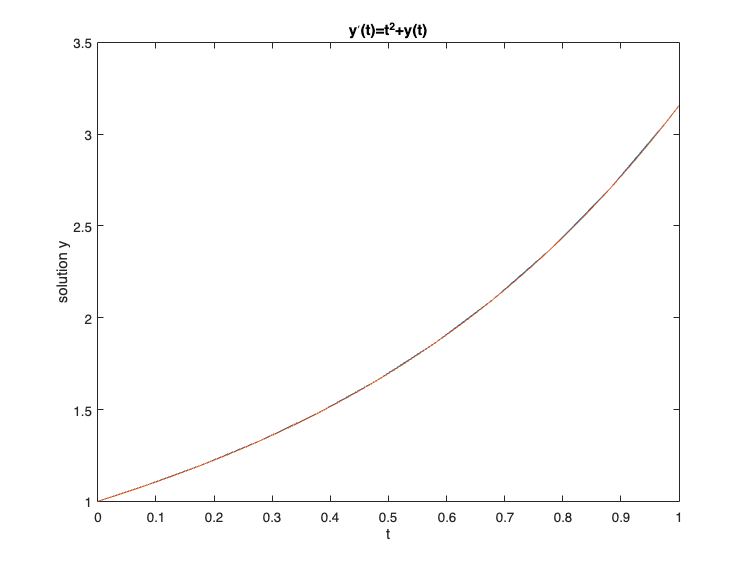

% Plot solution
plot(t1,y1,t2,y2)
xlabel('t')
ylabel('solution y')
title('y^{\prime}(t)=t^2+y(t)')

hold off

## PRACTIQUEM... 

### Exercici 1. 

 Resoleu els exercicis: 2,3,4,5,6,7, 8 i 11 del document practica12_edos_I.pdf disponible en el campus virtual.

#### **a) PVI  **$y^{\prime}(t)=-y(t)+t+1\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

## Respostes document --->  prac12_19maig_metodes_exercici_a.html

syms y(t)
eqn = diff(y,t) == -y+t+1;
cond = y(0) == 1;
ySol(t) = dsolve(eqn,cond)

$$ySol(t) = t+{\mathrm{e}}^{-t}$$

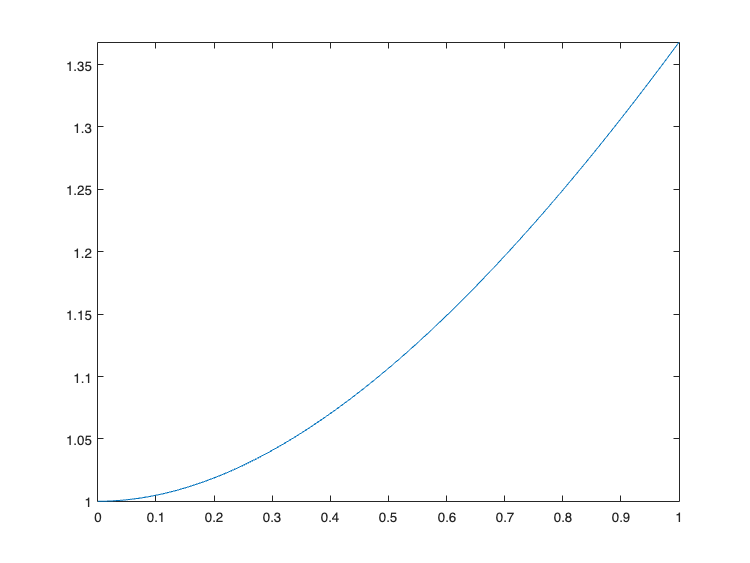

fplot(ySol,[0,1])

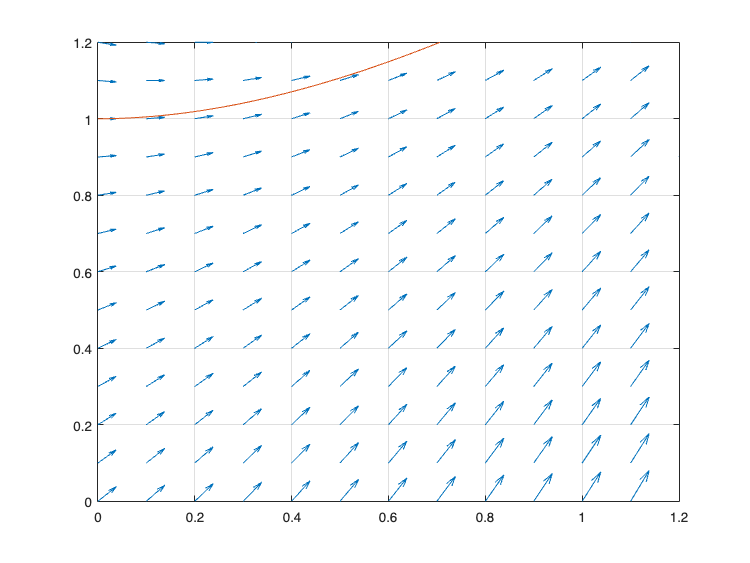


t=0:0.1:2; 
y=0:0.1:2;
[TT,YY] = meshgrid(t,y);
DT = ones(size(TT));
f = @(t,y)(-y+t+1);
DY = f(TT,YY);
% Gràfic
figure(1)
quiver(TT,YY,DT,DY);grid,axis([0,1.2,0,1.2])
hold on
fplot(ySol,[0,1]), hold off


a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(-y+t+1);
h = 0.1;
x = a:h:b; 
[ Y1 ] = Euler( f,a,b,h,alpha );
errorlocal = abs(Y1-double(ySol(x)))

errorlocal =             0    0.0048374    0.0087308     0.011818      0.01422     0.016041     0.017371     0.018288     0.018862     0.019149     0.019201


errorGlobal = abs(Y1(end)-double(ySol(b)))

errorGlobal =      0.019201

table(x',Y1',errorlocal','Variablenames',{'t','Euler','error_local'})

ans = 11×3 table
     t     Euler     error_local
    ___    ______    ___________
      0         1             0 
    0.1         1     0.0048374 
    0.2      1.01     0.0087308 
    0.3     1.029      0.011818 
    0.4    1.0561       0.01422 
    0.5    1.0905      0.016041 
    0.6    1.1314      0.017371 
    0.7    1.1783      0.018288 
    0.8    1.2305      0.018862 
    0.9    1.2874      0.019149 
      1    1.3487      0.019201 

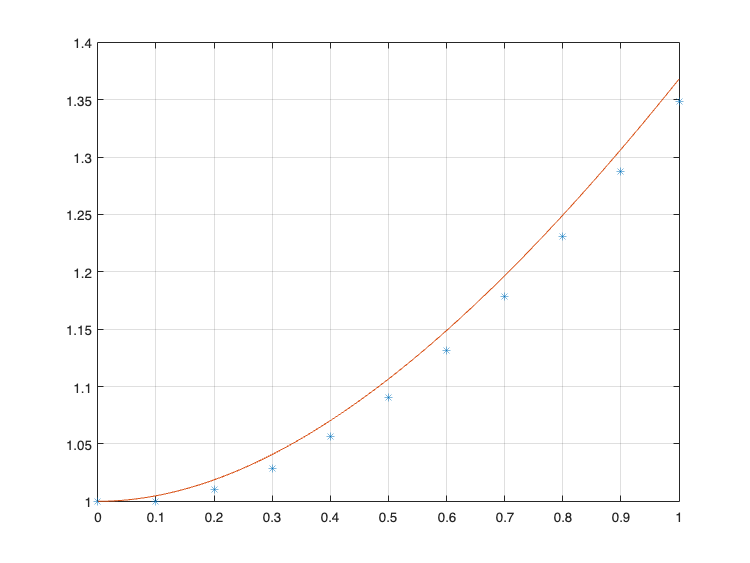

t=linspace(a,b);
plot(x,Y1,'*',t,ySol(t)),grid

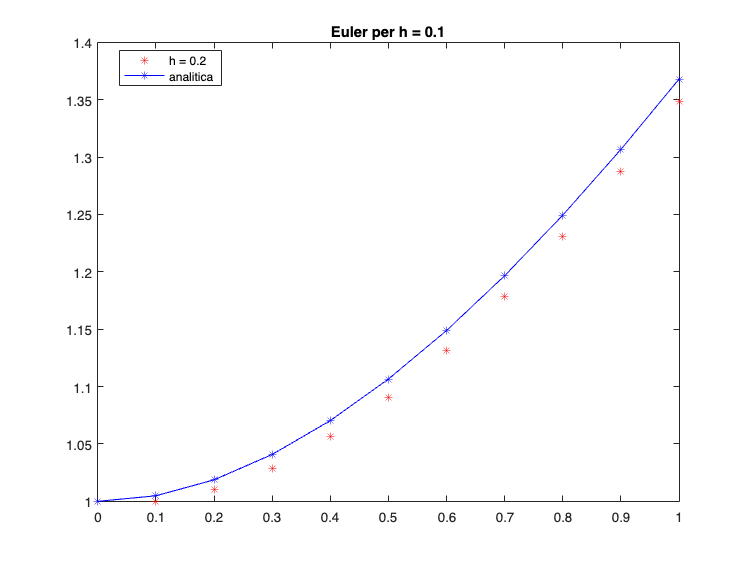

plot(x,Y1,'*r',x,ySol(x),'b-*'), title(['Euler per h = ', num2str(h)]), legend('h = 0.2','analitica','Location','best')
hold on

h = 0.05;
x = a:h:b; 

[ YK1 ] = RK4( f,a,b,h,alpha );
errorlocal = abs(YK1-double(ySol(x)));
errorGlobal = abs(YK1(end)-double(ySol(b)))

errorGlobal =    1.9976e-08

table(x',YK1',errorlocal','Variablenames',{'t','EulerMill','error_local'})

ans = 21×3 table
     t      EulerMill    error_local
    ____    _________    ___________
       0          1               0 
    0.05     1.0012      2.5826e-09 
     0.1     1.0048      4.9133e-09 
    0.15     1.0107      7.0106e-09 
     0.2     1.0187      8.8915e-09 
    0.25     1.0288      1.0572e-08 
     0.3     1.0408      1.2068e-08 
    0.35     1.0547      1.3393e-08 
     0.4     1.0703       1.456e-08 
    0.45     1.0876      1.5581e-08 
     0.5     1.1065      1.6468e-08 
    0.55     1.1269      1.7231e-08 
     0.6     1.1488      1.7881e-08 
    0.65      1.172      1.8426e-08 
     0.7     1.1966      1.8875e-08 
    0.75     1.2224      1.9237e-08 

t=linspace(a,b);
plot(x, Y1,'o', x,YK1,'*',t,ySol(t)),grid

Error using plot
Vectors must be the same length.

plot(x,ySol(x),'*',x,YK1,'*r'), title(['RK4 h = ', num2str(h)])

[ Y1 ] = Euler( f,a,b,h,alpha );
errorlocal = abs(Y1-double(ySol(x)))
errorGlobal = abs(Y1(end)-double(ySol(b)))
table(x',Y1',errorlocal','Variablenames',{'t','Euler','error_local'})
t=linspace(a,b);
plot(x,Y1,'*',t,ySol(t)),grid
plot(x,Y1,'*black',x,ySol(x),'b-*'), title(['Euler per h = ', num2str(h)]), legend('h = 0.1', 'h = 0.05', 'analitica','Location','best')
hold off

a = 0; alpha = 1;    % y(a) = alpha
b = 1;               % y(b) = ...
f = @(t,y)(-y+t+1);
h = 0.1;
x = a:h:b; 


[ YH1 ] = EulerMill( f,a,b,h,alpha );
errorlocal = abs(YH1-double(ySol(x)));
errorGlobal = abs(YH1(end)-double(ySol(b)))

errorGlobal =    0.00066154

table(x',YH1',errorlocal','Variablenames',{'t','EulerMill','error_local'})

ans = 11×3 table
     t     EulerMill    error_local
    ___    _________    ___________
      0          1               0 
    0.1      1.005      0.00016258 
    0.2      1.019      0.00029425 
    0.3     1.0412       0.0003994 
    0.4     1.0708       0.0004819 
    0.5     1.1071      0.00054511 
    0.6     1.1494      0.00059193 
    0.7     1.1972      0.00062492 
    0.8       1.25      0.00064629 
    0.9     1.3072      0.00065795 
      1     1.3685      0.00066154 

t=linspace(a,b);
plot(x, Y1,'o', x,YH1,'*',t,ySol(t)),grid

Error using plot
Vectors must be the same length.

plot(x,ySol(x),'*',x,YH1,'*r'), title(['Euler per h = ', num2str(h)])

#### **b) PVI  **$y^{\prime}(t)=te^{3t}-2y(t)\,,\quad y(0)=0,\quad 0\leq t\leq 1\,.$  

%% Respostes document --->  prac12_19maig_metodes_exercici_b.html   

#### **c) PVI  **$y^{\prime}(t)=\cos(2t)+\sin(3t)\,,\quad y(0)=1,\quad 0\leq t\leq 1\,.$

%% Respostes document --->  prac12_19maig_metodes_exercici_c.html   

### Exercici 2. 

Resoleu l'exercici 10 del document practica12_edos_I.pdf disponible en el campus virtual.

%% Respostes document --->  prac12_19maig_metodes_exercici_2.html   

function [ w ] = Euler(f,a,b,h,alpha)
% Mètode d'Euler
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    w(i+1)=w(i)+h*f(t(i),w(i));
end
end
%-----------------------------------------
function  w  = EulerMod( f,a,b,h,alpha )
% Mètode d'Euler Modificat o punto medio
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    k1 = w(i)+h/2*f(t(i),w(i));
    w(i+1)=w(i)+h*f(t(i)+h/2,k1);
end
end
%-----------------------------------------
function  w  = EulerMill( f,a,b,h,alpha )
% Mètode d'Euler Millorat o HEUN
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    k1 = h*f(t(i),w(i));
    k2 = h*f(t(i+1),w(i)+k1);
    w(i+1)=w(i)+1/2*(k1+k2);
end
end
%----------------------------------------
function  w  = RK4( f,a,b,h,alpha )
% Mètode RK4
t=[a:h:b];
N=length(t);
w(1)=alpha;
for i=1:N-1
    k1 = h*f(t(i),w(i));
    k2 = h*f(t(i)+h/2,w(i)+k1/2);
    k3 = h*f(t(i)+h/2,w(i)+k2/2);
    k4 = h*f(t(i+1),w(i)+k3);
    w(i+1)=w(i)+1/6*(k1+2*k2+2*k3+k4);
end
end